close all;
clear all;
clc;

% Set up communications
arduino = serialport("COM5", 9600, "Timeout", 25); 
pause(1);

x = 0:100;
numLEDs = 4; % Number of LEDs
y = zeros(numLEDs, 101);
v = zeros(numLEDs, 101);
c = zeros(numLEDs, 101);
r = zeros(numLEDs, 101);

photoResistor = 10000;

for led = 1:numLEDs
    for K = 0:100
        flush(arduino);
        write(arduino, 2, 'string');
        pause(0.5);
        a = read(arduino, 4, 'string');
        flush(arduino);
        y(led, K+1) = str2double(a);
        disp([led, K, y(led, K+1)]);
    end
    
    v(led, :) = (y(led, :) / 1023) * 5;
    c(led, :) = v(led, :) / photoResistor;
    r(led, :) = photoResistor * (5 - v(led, :)) ./ v(led, :);
    
    
    disp('Press any key to continue to the next LED...');
    pause;
    close;
end

     1     0   363

     1     1   386

     1     2   404

     1     3   431

     1     4   459

     1     5   471

     1     6   500

     1     7   518

     1     8   521

     1     9   530

     1    10   539

     1    11   559

     1    12   595

     1    13   578

     1    14   585

     1    15   596

     1    16   611

     1    17   617

     1    18   624

     1    19   634

     1    20   640

     1    21   646

     1    22   653

     1    23   660

     1    24   666

     1    25   689

     1    26   676

     1    27   697

     1    28   683

     1    29   705

     1    30   690

     1    31   696

     1    32   704

     1    33   726

     1    34   712

     1    35   732

     1    36   719

     1    37   740

     1    38   741

     1    39   746

     1    40   747

     1    41   731

     1    42   733

     1    43   742

     1    44   761

     1    45   765

     1    46   767

     1    47   769

     1    48   750

     1    49   774



Press any key to continue to the next LED...


     2     0   353

     2     1   374

     2     2   410

     2     3   431

     2     4   459

     2     5   472

     2     6   492

     2     7   504

     2     8   521

     2     9   527

     2    10   541

     2    11   552

     2    12   560

     2    13   569

     2    14   576

     2    15   587

     2    16   590

     2    17   596

     2    18   604

     2    19   609

     2    20   619

     2    21   621

     2    22   637

     2    23   639

     2    24   646

     2    25   645

     2    26   650

     2    27   653

     2    28   662

     2    29   662

     2    30   663

     2    31   668

     2    32   670

     2    33   678

     2    34   682

     2    35   684

     2    36   683

     2    37   690

     2    38   690

     2    39   694

     2    40   698

     2    41   701

     2    42   706

     2    43   705

     2    44   708

     2    45   711

     2    46   715

     2    47   716

     2    48   718

     2    49   722



Press any key to continue to the next LED...


     3     0   345

     3     1   374

     3     2   433

     3     3   460

     3     4   499

     3     5   519

     3     6   542

     3     7   560

     3     8   580

     3     9   590

     3    10   607

     3    11   622

     3    12   631

     3    13   643

     3    14   653

     3    15   662

     3    16   669

     3    17   678

     3    18   685

     3    19   696

     3    20   703

     3    21   706

     3    22   713

     3    23   716

     3    24   725

     3    25   729

     3    26   733

     3    27   737

     3    28   747

     3    29   749

     3    30   751

     3    31   758

     3    32   760

     3    33   769

     3    34   771

     3    35   775

     3    36   774

     3    37   776

     3    38   780

     3    39   783

     3    40   785

     3    41   788

     3    42   793

     3    43   793

     3    44   796

     3    45   800

     3    46   802

     3    47   806

     3    48   808

     3    49   810



Press any key to continue to the next LED...


     4     0   382

     4     1   396

     4     2   412

     4     3   426

     4     4   445

     4     5   455

     4     6   469

     4     7   476

     4     8   492

     4     9   499

     4    10   510

     4    11   521

     4    12   526

     4    13   542

     4    14   552

     4    15   560

     4    16   567

     4    17   573

     4    18   577

     4    19   584

     4    20   595

     4    21   597

     4    22   604

     4    23   608

     4    24   614

     4    25   623

     4    26   624

     4    27   629

     4    28   634

     4    29   638

     4    30   643

     4    31   647

     4    32   652

     4    33   654

     4    34   661

     4    35   664

     4    36   666

     4    37   670

     4    38   673

     4    39   677

     4    40   681

     4    41   683

     4    42   687

     4    43   689

     4    44   695

     4    45   696

     4    46   698

     4    47   701

     4    48   708

     4    49   709



Press any key to continue to the next LED...


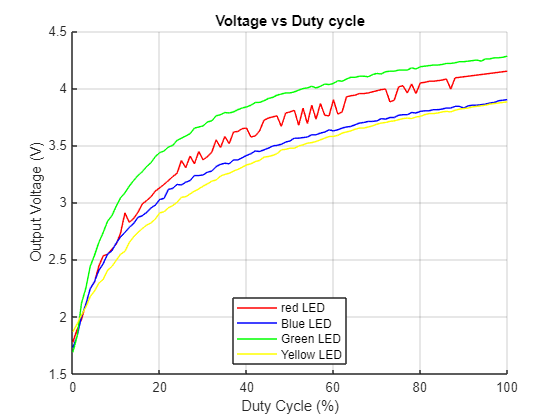



    figure;
    hold on
    plot(x, v(1, :), 'r-', 'MarkerFaceColor', 'red');
    plot(x, v(2, :), 'b-', 'MarkerFaceColor', 'blue');
    plot(x, v(3, :), 'g-', 'MarkerFaceColor', 'green');
    plot(x, v(4, :), 'y-', 'MarkerFaceColor', 'yellow');
    hold off
    grid on;
    xlabel('Duty Cycle (%)');
    ylabel('Output v (V)');
    title(['Voltage vs Duty cycle']);
    legend('red LED', 'Blue LED', 'Green LED', 'Yellow LED');
    legend('Location', 'south');

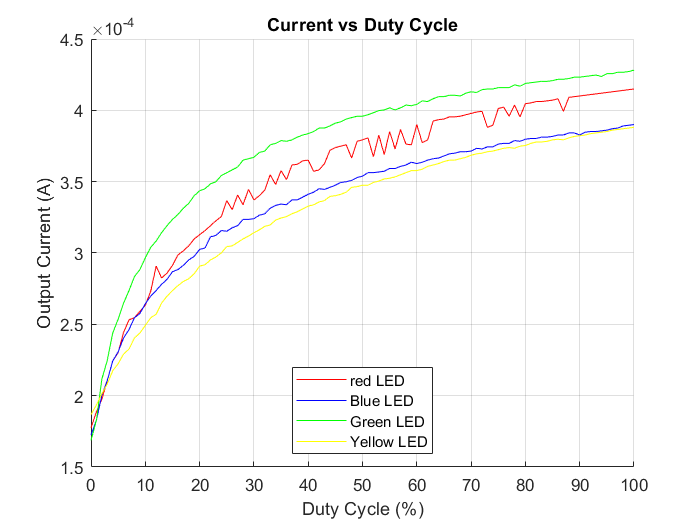


    % c
    figure;
    hold on
    plot(x, c(1, :), 'r-', 'MarkerFaceColor', 'red');
    plot(x, c(2, :), 'b-', 'MarkerFaceColor', 'blue');
    plot(x, c(3, :), 'g-', 'MarkerFaceColor', 'green');
    plot(x, c(4, :), 'y-', 'MarkerFaceColor', 'yellow');   
    grid on;
    xlabel('Duty Cycle (%)');
    ylabel('Output c (A)');
    title('Current vs Duty Cycle');
    legend('red LED', 'Blue LED', 'Green LED', 'Yellow LED');
    legend('Location', 'south');

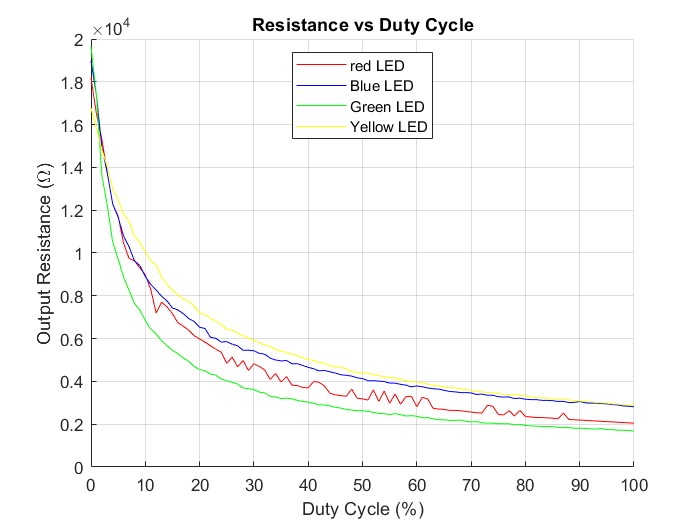


    % r
    figure;
    hold on
    plot(x, r(1, :), 'r-', 'MarkerFaceColor', 'red');
    plot(x, r(2, :), 'b-', 'MarkerFaceColor', 'blue');
    plot(x, r(3, :), 'g-', 'MarkerFaceColor', 'green');
    plot(x, r(4, :), 'y-', 'MarkerFaceColor', 'yellow');   
    grid on;
    xlabel('Duty Cycle (%)');
    ylabel('Output Resistence (\Omega)');
    title('r vs Duty Cycle');
    legend('red LED', 'Blue LED', 'Green LED', 'Yellow LED');
    legend('Location', 'north');


delete(arduino);
clear arduino;